clear
clc
n=40;
%numero de diferenciales de polo en la distribucion
anchom=input('Introduce el ancho del iman:')

anchom = 1

sizem=input('Introduce la distancia entre los polos:')

sizem = 1

pnet=input('Introduce la carga magnetica de cualquera de los polos:')

pnet = 46

p1=pnet/n

p1 = 1.1500

p2=p1

p2 = 1.1500

lambda=(pnet)/(anchom); %Carga magnetica de cada dp
lambda1=pnet/anchom

lambda1 = 46

%lambda1=(-p2)/(anchom);

mm=2*p1*sizem

mm = 2.3000

mm=-2

mm = -2

f1=@(x)sizem./2;
f2=@(x)-sizem./2;

%Iman Visual
%Norte
norte = polyshape([-anchom/2,-anchom/2,anchom/2,anchom/2],[sizem/2,0,0,sizem/2]);
plot(norte,'FaceColor','red')
axis equal
hold on


%Sur
sur = polyshape([-anchom/2,-anchom/2,anchom/2,anchom/2],[0,-sizem/2,-sizem/2,0]);
plot(sur,'FaceColor','blue','FaceAlpha',0.1)





xqn1=linspace(-anchom/2,anchom/2,n); %Coordenadas x 
yqn1=ones(length(xqn1))*f1(xqn1); %Cooredenadas y
qn1=ones(size(xqn1)).*lambda; %Cargas*lambda
plot(xqn1,yqn1,'R*')

xqn2=linspace(-anchom/2,anchom/2,n); %Coordenadas x 
yqn2=ones(length(xqn1))*f2(xqn1); %Cooredenadas y
qn2=ones(size(xqn1)).*lambda1; %Cargas*lambda
plot(xqn2,yqn2,'b*')


%meshgid
po=15

po = 15

x=linspace(-anchom/2-po,anchom/2+po,n);
y=linspace(-sizem/2-po,sizem/2+po,n);
[X,Y]=meshgrid(x,y);
x3=X;
y3=Y;

pt=[qn1,qn2]

pt =     46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46    46



distx=[];
disty=[];
num1=[];
num2=[];
num3=[];
disty2=[]


disty2 =

     []



k=1e-7; 
p=1;
for i=1:length(xqn1) %Distancias en X  de cargas y puntos y Y
    distx=[distx;x3-xqn1(i)];
    disty=[disty;y3-yqn1(i)];   %Cambiar a una sola xnq1->pt
    disty2=[disty2;y3-yqn2(i)];
     
end


r1=sqrt(distx.^2+disty.^2);%Distancia polo norte
r2=sqrt(distx.^2+disty2.^2);%Distancia polo sur
%r3=sqrt((2.*distx).^2+(disty+disty2).^2)
r3=((1./r1.^2)-(1./r2.^2));
r3=[r3;r3];
distx=[distx;distx]

distx =   -15.0000  -14.2051  -13.4103  -12.6154  -11.8205  -11.0256  -10.2308   -9.4359   -8.6410   -7.8462   -7.0513   -6.2564   -5.4615   -4.6667   -3.8718   -3.0769   -2.2821   -1.4872   -0.6923    0.1026    0.8974    1.6923    2.4872    3.2821    4.0769    4.8718    5.6667    6.4615    7.2564    8.0513    8.8462    9.6410   10.4359   11.2308   12.0256   12.8205   13.6154   14.4103   15.2051   16.0000
  -15.0000  -14.2051  -13.4103  -12.6154  -11.8205  -11.0256  -10.2308   -9.4359   -8.6410   -7.8462   -7.0513   -6.2564   -5.4615   -4.6667   -3.8718   -3.0769   -2.2821   -1.4872   -0.6923    0.1026    0.8974    1.6923    2.4872    3.2821    4.0769    4.8718    5.6667    6.4615    7.2564    8.0513    8.8462    9.6410   10.4359   11.2308   12.0256   12.8205   13.6154   14.4103   15.2051   16.0000
  -15.0000  -14.2051  -13.4103  -12.6154  -11.8205  -11.0256  -10.2308   -9.4359   -8.6410   -7.8462   -7.0513   -6.2564   -5.4615   -4.6667   -3.8718   -3.0769   -2.2821   -1.4872   -0.6923

disty=[disty;disty2]

disty =   -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000
  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051  -15.2051
  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103  -14.4103

Exx=[]


Exx =

     []



Eyy=[]


Eyy =

     []



for g=1:length(xqn1)*2
    Exx=[Exx;k.*pt(g).*r3(p:g*length(x),1:length(x)).*distx(p:g*length(x),1:length(x))];
    Eyy=[Eyy;k.*pt(g).*r3(p:g*length(x),1:length(x)).*disty(p:g*length(x),1:length(x))];
    %num3=[num3;k.*qn1(g).*r(p:g*length(x),1:length(x)).*disty2(p:g*length(x),1:length(x))];
    p=(g*length(x))+1 ;
end

 ex=Exx./[r1;r2];
Ex=zeros(length(x),length(x));
m=1;
for q=1:length(x)*2
    Ex=Ex+ex(m:q*length(x),1:length(x));%Magnnitudes en 
    m=q*length(x)+1;
end

ey=Eyy./[r1;r2]

ey = 	1.0e+-3 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

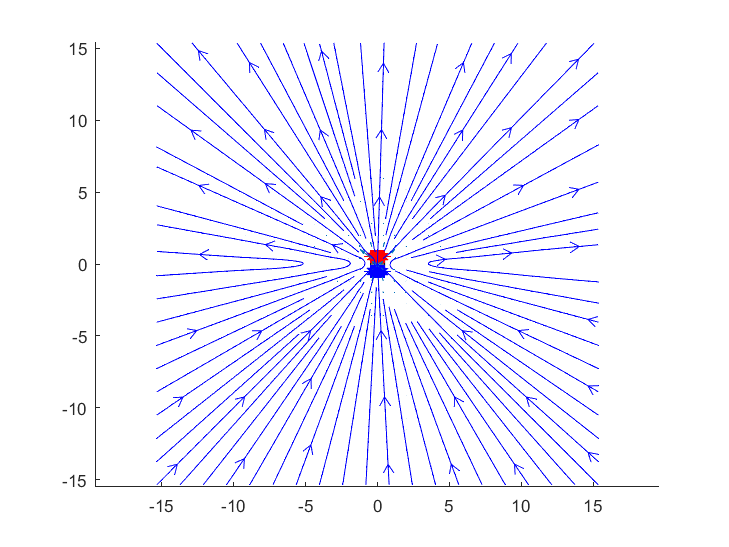

 Ey=zeros(length(x),length(x));

a=1;
for r=1:length(x)*2
    Ey=Ey+ey(a:r*length(x),1:length(x));
    a=r*length(x)+1;
end
quiver(X,Y,Ex,Ey)
streamslice(X,Y,Ex,Ey)